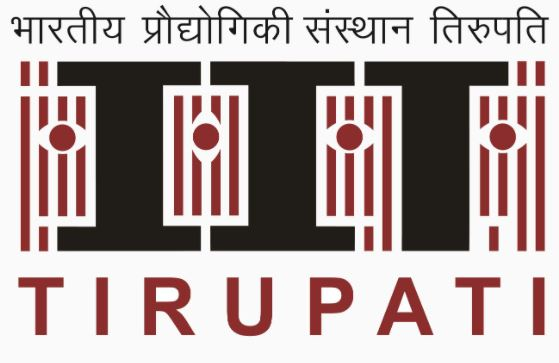

### **Digital Signal Processing Laboratory**

**LabSheet-07**

Name: Suriyaa MM

Roll Number: EE23B054

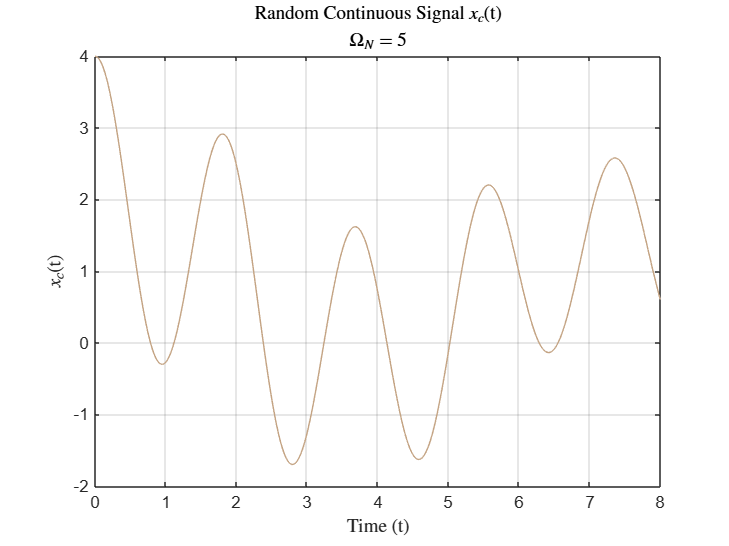

% colours for good visualization
COLOUR_BROWN    = "#c4a484";
COLOUR_RED      = "#fc1758";
COLOUR_BLUE     = "#4a8af0";
COLOUR_GREY     = "#A9A9A9";

% generate a continuous random cosine signal which is mixture of different
% frequencies
function x_c = compute_x_c(t, Omega_N, I)
    % pre-allocate and initialize them with zeros
    x_c = zeros(size(t));  
    for i = 1:I
        omega_i = Omega_N * rand;  
        x_c = x_c + cos(omega_i * t);  
    end
end

% parameters
Omega_N = 5;  
I = 4;      
T_max = 8;
delta_t = 0.001;
t = 0:delta_t:T_max; 

% computing x_c(t)
x_c = compute_x_c(t, Omega_N, I);

% plotting x_c(t)
figure;
plot(t, x_c, Color = COLOUR_BROWN);
xlabel('Time (t)', Interpreter = 'latex');
ylabel('$x_c$(t)', Interpreter = 'latex');
title('Random Continuous Signal $x_c$(t)', ...
    Interpreter = 'latex');
subtitle(['$\Omega _N$ = ', num2str(Omega_N)], Interpreter = 'latex')
grid on;

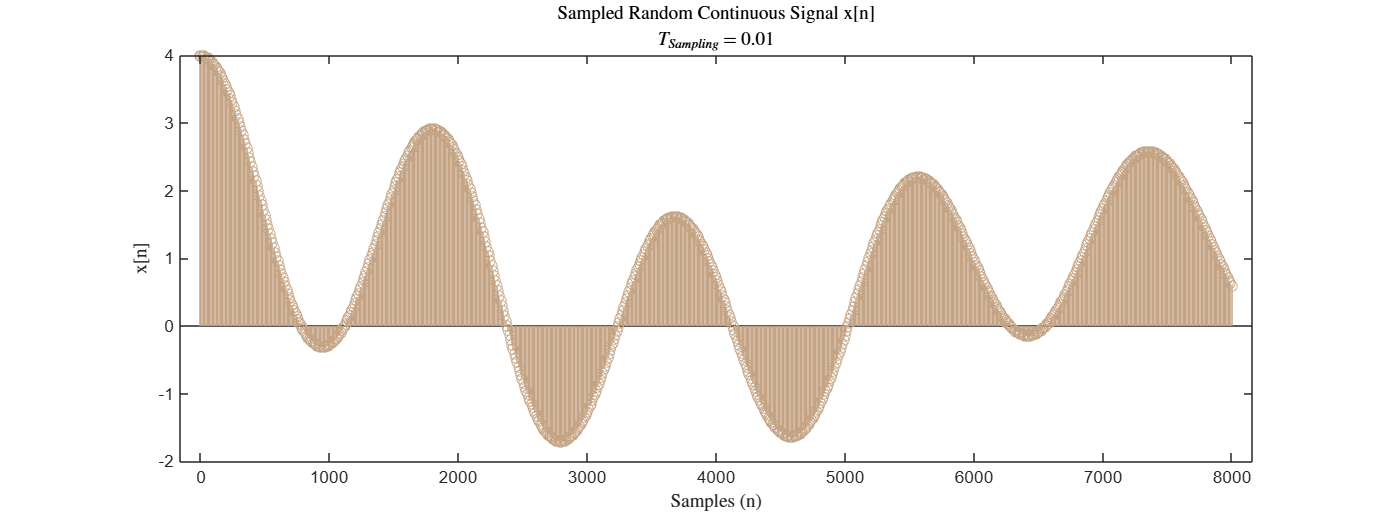


% sampling period
T_sampling = 0.01;

% sampling x_c(t)
t_sampled = 0:T_sampling:T_max;
sampled_indices = round(t_sampled/delta_t) + 1;
x_n = x_c(sampled_indices);

% plotting x[n]
figure;
figProps = gcf;
figProps.Position(3) = figProps.Position(3) * 4;
figProps.Position(4) = figProps.Position(4) * 2;
stem(sampled_indices, x_n, Color = COLOUR_BROWN);
xlabel('Samples (n)', Interpreter = 'latex');
ylabel('x[n]', Interpreter = 'latex');
title('Sampled Random Continuous Signal x[n]', Interpreter = 'latex');
subtitle(['$T_{Sampling}$ = ', num2str(T_sampling)], Interpreter = 'latex');

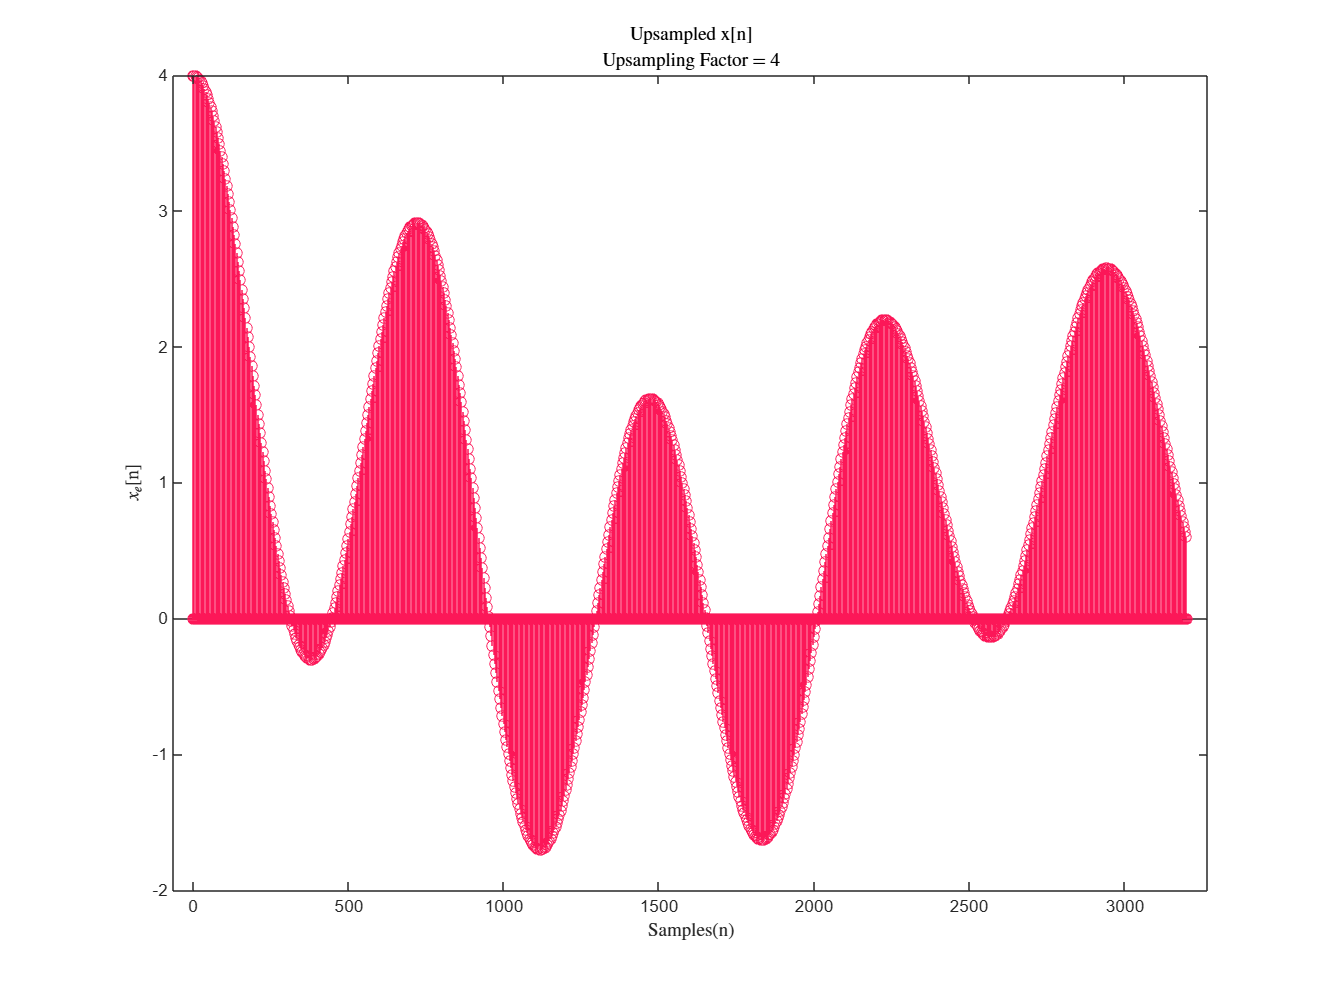


% upsampling the sampled signal x[n]
L = 4;
x_e = zeros(1, length(x_n) * L);
% upsampled signal
x_e(1:L:end) = x_n;

% plotting x_e[n]
figure;
figProps = gcf;
figProps.Position(3) = figProps.Position(3) * 4;
figProps.Position(4) = figProps.Position(4) * 4;
stem(x_e, Color = COLOUR_RED);
xlabel('Samples(n)', Interpreter = 'latex');
ylabel('$x_e$[n]', Interpreter = 'latex');
title('Upsampled x[n]', Interpreter = 'latex');
subtitle(['Upsampling Factor = ', num2str(L)], Interpreter = 'latex');

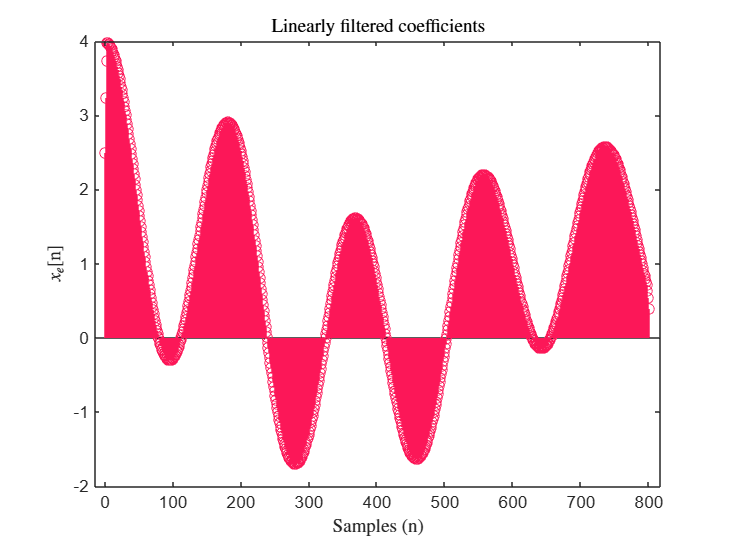


% computing linear interpolation function
function h = h_lin(L)
    % length of filter
    filter_length = 2 * L - 1;  
    % pre-allocating filter and initialize with zeros
    h = zeros(1, filter_length);

    for n = 0:L-1
        h(L + n) = (L - n) / L; 
        h(L - n) = (L - n) / L; 
    end

    h = h/sum(h);
end

h = h_lin(L);

% computing x_i[n]
x_i = conv(x_n, h, 'same');

% plotting x_i[n]
figure;
stem(x_i, Color = COLOUR_RED);
xlabel('Samples (n)', Interpreter = 'latex');
ylabel('$x_e$[n]', Interpreter = 'latex');
title('Linearly filtered coefficients', Interpreter = 'latex');

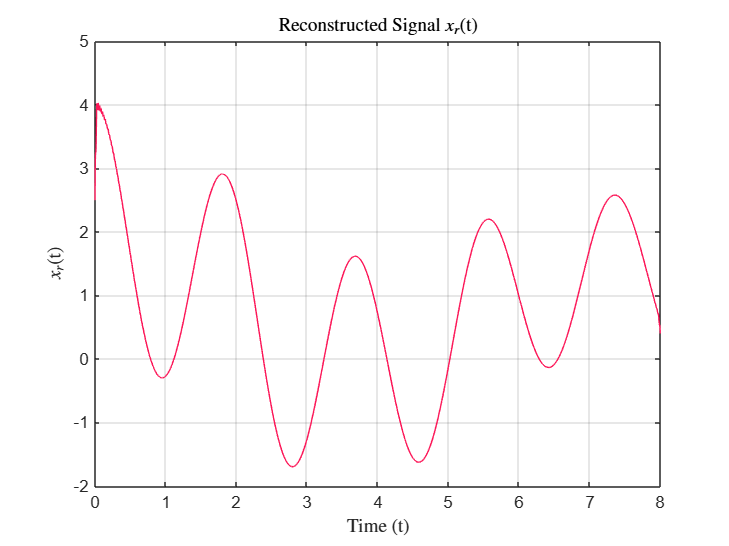


% pre-allocating x_r and initializing it with zeros
x_r = zeros(size(t));

% sinc interpolation (low pass filter) for reconstruction
for n = 0:length(x_i)-1
    x_r = x_r + x_i(n+1) * sinc((t - n * T_sampling) / T_sampling);
end

% plotting x_r(t)
figure;
plot(t, x_r, Color = COLOUR_RED);
xlabel('Time (t)', Interpreter = 'latex');
ylabel('$x_r$(t)', Interpreter = 'latex');
title('Reconstructed Signal $x_r$(t)', Interpreter = 'latex');
grid on;

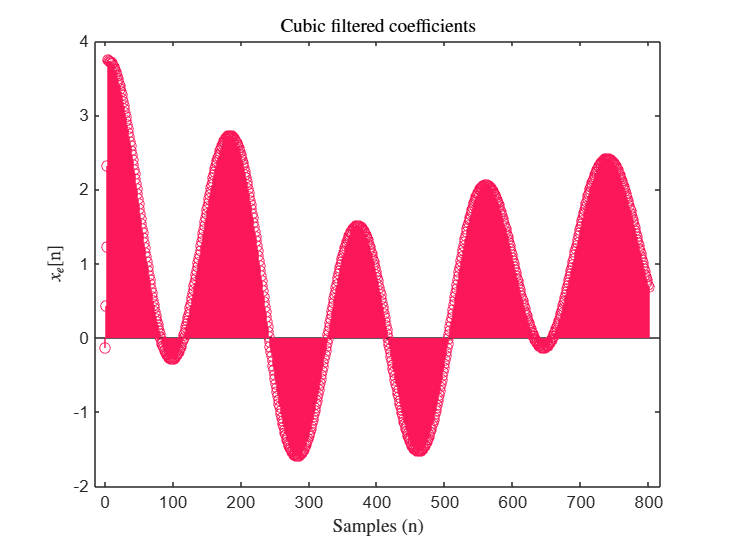


% custom cubic/quadratic interpolation filter
function h = cubic_filter(L, a)
    
    filter_length = 2 * L + 1; 
    h = zeros(1, filter_length);
    for n = 0:L
        h(n + 1) = (a + 2) * (abs(n / L))^3 - (a + 3) * (abs(n / L))^2 + 1;
    end

    for n = L+1:2*L
        h(n + 1) = a * (abs(n / L))^3 - 5 * (abs(n / L))^2 + 8 * a * (abs(n / L)) - 4 * a;
    end

    % filter normalization
    h = h / sum(abs(h));
end

h = -cubic_filter(L, -0.5);

% computing x_i[n]
x_i = conv(x_n, h, 'same');

% plotting x_i[n]
figure;
stem(x_i, Color = COLOUR_RED);
xlabel('Samples (n)', Interpreter = 'latex');
ylabel('$x_e$[n]', Interpreter = 'latex');
title('Cubic filtered coefficients', Interpreter = 'latex');

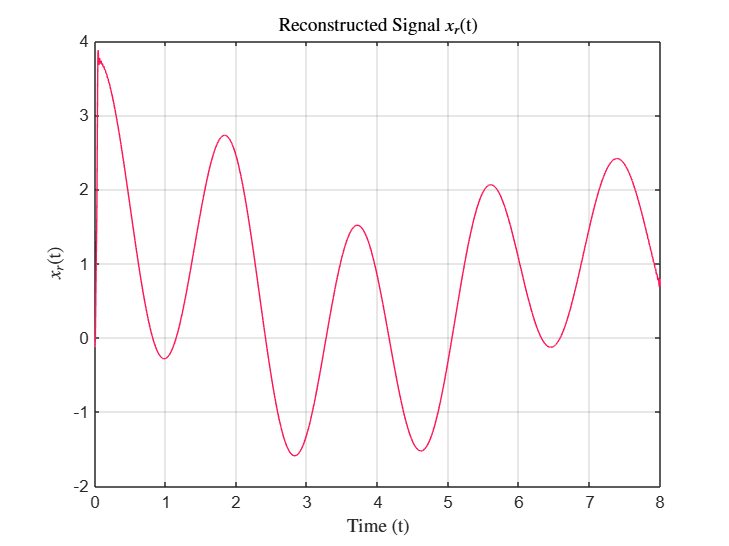


% pre-allocating x_r and initializing it with zeros
x_r = zeros(size(t));

% sinc interpolation (low pass filter) for reconstruction
for n = 0:length(x_i)-1
    x_r = x_r + x_i(n+1) * sinc((t - n * T_sampling) / T_sampling);
end

% plotting x_r(t)
figure;
plot(t, x_r, Color = COLOUR_RED);
xlabel('Time (t)', Interpreter = 'latex');
ylabel('$x_r$(t)', Interpreter = 'latex');
title('Reconstructed Signal $x_r$(t)', Interpreter = 'latex');
grid on;

**Observations**

- **Continuous Signal Generation**:

- A random continuous cosine signal $x_c(t)$ is generated by summing multiple cosine waves of random frequencies. The function `compute_x_c` takes in a time vector `t`, a frequency limit `Omega_N`, and a count `I` of cosine components. The resulting signal, $x_c(t)$, is visualized.

- **Sampling**:

- The signal $x_c(t)$ is sampled at intervals of $T_{Sampling}$, producing a discrete sampled signal $x[n]$. Indices corresponding to sampling points are calculated to match the $t_{sampled}$ intervals, and the sampled signal is plotted.

- **Upsampling**:

- The sampled signal  $x[n]$ is upsampled by a factor `L`, creating an expanded signal `x_e` where the original samples are spaced `L` indices apart, with zeros in between. This upsampled signal is also plotted for visualization.

- **Linear Interpolation Filtering**:

- A linear interpolation filter `h` is computed with length `2*L - 1` to smooth the upsampled signal. This filter assigns weights to neighbors based on distance, creating a smooth transition between samples. The filtered signal `x_i` is obtained by convolving $x[n]$ with `h` and plotted.

- **Sinc-Based Reconstruction**:

- Using sinc interpolation, a continuous-time reconstructed signal $x_r(t)$ is obtained from `x_i`. This low-pass filter-based approach aims to recover the original signal from the sampled points. The reconstructed signal is plotted.

- **Quadratic/Cubic Interpolation Filtering**:

- An alternative quadratic/cubic filter function `cubic_filter` is defined for smoother interpolation, parameterized by `a`. This filter uses a cubic interpolation formula with conditions for different ranges of `n`. For a smoother effect, it’s normalized. The `x_i` signal is filtered using this filter, then sinc-interpolated, and plotted for comparison.